** 3.3 행렬의 나눗셈**

단위행렬(identity matrix or unity matrix) **I**

대각선 원소가 모두 1이고 그 외의 원소는 0인 정방행렬(square matrix)

MATLAB에서는 **eye**(n) 명령어 사용

행렬(또는 벡터)에 단위행렬 I를 곱해도 불변. (스칼라에 1을 곱한 경우와 유사) 

I=eye(3);
A= [7 4 6;3 1 8;2 5 4];
B=A*I;
C=I*A;
I

I =      1     0     0
     0     1     0
     0     0     1


A

A =      7     4     6
     3     1     8
     2     5     4


B

B =      7     4     6
     3     1     8
     2     5     4


C

C =      7     4     6
     3     1     8
     2     5     4


**역핼렬**

정방행렬인 A와 B 에 대하여

**AB = BA = ****I **를 만족하면 **A**와 **B**는 서로 역행렬

**A**=**IB^(-1)** =**B^(-1)**  또는  **B**=**IA^(-1)** =**A^(-1)**

A= [7 4 6;3 1 8;2 5 4];
B=inv(A);
C=A*B;
D=B*A;
A

A =      7     4     6
     3     1     8
     2     5     4


B

B =     0.2278   -0.0886   -0.1646
   -0.0253   -0.1013    0.2405
   -0.0823    0.1709    0.0316


C

C =     1.0000    0.0000    0.0000
   -0.0000    1.0000         0
   -0.0000    0.0000    1.0000


D

D =     1.0000   -0.0000   -0.0000
         0    1.0000         0
   -0.0000         0    1.0000


E=A^-1;
E

E =     0.2278   -0.0886   -0.1646
   -0.0253   -0.1013    0.2405
   -0.0823    0.1709    0.0316


F=A*(A^-1);
F

F =     1.0000    0.0000    0.0000
   -0.0000    1.0000         0
   -0.0000    0.0000    1.0000


행렬 A의 행렬식(determinant)

|A|로 표시

MATLAB 명령 **det(A)**사용

A= [1 2;3 1];
A

A =      1     2
     3     1


det(A)

ans = -5

A= [1 2 0;0 1 1;3 0 1];
A

A =      1     2     0
     0     1     1
     3     0     1


det(A)

ans = 7

행렬의 나눗셈

**\(자판에 따라서 원 표시) : ** 왼쪽 나눗셈 (left division)

**/ : **오른쪽 나눗셈 (right division)

**\** : 왼쪽 나눗셈 (Left division)

예 : 연립방정식 **Ax=b** 의 해를 구하는 두가지 방법

**(1) inv 사용 : x = ****inv****(A)*b**

**(2) 원쪽 나눗셈 사용: **•**x = A\b**

**(매트랩에서는 (2) 방법이 좀 더 정확하다. 그러나 소수점 아랫자리에서 일어나는 일이라서 구별하기 어려울 때가 대부분.)**

4/8             % 스칼라 오른쪽

ans = 0.5000

4\8 		 % 스칼라 왼쪽

ans = 2

A=[4 -2 6;2 8 2;6 10 3];
b=[8;4;0];
x1=(A^-1)*b;   % 역행렬
x2=inv(A)*b;   % 역행렬
x3 = A\b;     % 왼쪽 나눗셈
x1

x1 =    -1.8049
    0.2927
    2.6341


x2

x2 =    -1.8049
    0.2927
    2.6341


x3

x3 =    -1.8049
    0.2927
    2.6341


**/ **: 오른쪽 나눗셈 (Right division) 

연립 방정식 xC=d 해를 구하는 두 가지 방법 ( x와 d는 행벡터)

**(1) inv 사용 : x = d*inv****(C)**

**(2) 오른쪽 나눗셈 사용: x =d/C**

C=[4 -2 6;2 8 2;6 10 3];
d=[8 4 0];
x1=d/C;
x2=d*inv(A);
x1

x1 =    -0.3415   -2.6341    2.4390


x2

x2 =    -0.3415   -2.6341    2.4390


%확인하기
x1*C

ans =     8.0000    4.0000    0.0000


x2*C

ans =     8.0000    4.0000         0


x1+x2+x3=400, 10x1+5x2=1600 의 해를 구하라.

미지수 3개, 식은 2개 -> 일반적으로 단일 해를 구할 수 없다.

이를 한번에 matlab에선 pinv로 푼다.

A = [1,1,1;10,5,0];
b = [400;1600];
x = pinv(A)*b;
x

x =    93.3333
  133.3333
  173.3333


또 pinv는 미지수보다 식이 더 많을 때도 사용할 수 있다.

이런 경우가 실제 상황에서 매우 자주 일어난다.

A=[0 1;5 1;10 1]; b=[2; 6; 11];
A

A =      0     1
     5     1
    10     1


b

b =      2
     6
    11


x = pinv(A)*b

x =     0.9000
    1.8333


**3.4 원소별 연산**

덧셈과 뺄셈 처럼 두 행렬의 원소와 원소끼리 곱셈 나누셈, 거듭제곱을 연산 

원소별 연산은 점 ( **.** ) 뒤에 연산기호를 붙이면 된다:

**.* (원소별 곱셈),   .^ (원소별 거듭제곱),   ./ (우측 나눗셈),  .\ (좌측 나눗셈)**

**이 연산에는 두 행렬 또는 벡터끼리 차원이 같아야 한다.**

A=[2 6 3;5 8 4];
B=[1 4 10;3 2 7];
C=A.*B;
A

A =      2     6     3
     5     8     4


B

B =      1     4    10
     3     2     7


C

C =      2    24    30
    15    16    28


%D= A*B % 일반 행렬 곱셈하기에는 서로 차원이 안맞다.

C=A./B

C =     2.0000    1.5000    0.3000
    1.6667    4.0000    0.5714


2.^B

ans =            2          16        1024
           8           4         128


**행렬의 ****원소별**** 연산의 예**

**y=x^3-4**x^**2**의 그래프를 **x=[0:5]**에서 그려라.

그래프를 그릴 때 독립변수와 종속변수를 모두 벡터로 간주.

x=[0:5];
y=x.^3-4*x.^2;
y

y =      0    -3    -8    -9     0    25


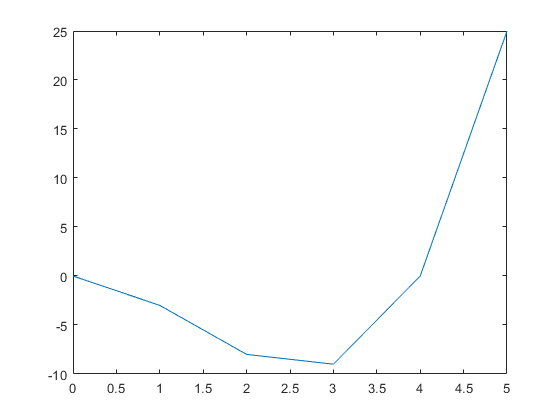

plot(x,y);